%clearing crap
clear all
clf

%declaring variables
syms t

%importing actual count data
counts = importdata("raw count.txt");

%plotting initial data points
plot(counts(:,1),counts(:,2),"o")

hold on %plotting on same curve

%coefficients for standard sum of squares method
N11 = 1620.864;
N12 = 283.4383;
t11 = 1.355948;
t12 = 2.703504;

%exponential decay curve
eqn1(t) = (N11/t11)*exp(-t/t11) + (N12/t12)*exp(-t/t12);

%plotting
fplot(eqn1,"--g")

hold on %plotting on same curve

%coefficients for absolute percentage difference method
N21 = 1564.973;
N22 = 325.5901;
t21 = 1.361556;
t22 = 2.45331;

%exponential decay curve
eqn2(t) = (N21/t21)*exp(-t/t21) + (N22/t22)*exp(-t/t22);

%plotting
fplot(eqn2,"--r")

hold on %plotting on same curve

%coefficients for absolute logarythm method
N31 = 1574.079;
N32 = 281.9486;
t31 = 1.417415;
t32 = 2.512624;

%exponential decay curve
eqn3(t) = (N31/t31)*exp(-t/t31) + (N32/t32)*exp(-t/t32);

%plotting
fplot(eqn3,"--c")

hold off %end plotting

%setting limits
xlim([0 12])
ylim([0 800])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;
grid on;

%labelling gprah
xlabel("Time [hrs]")
ylabel("Count [hrs^{-1}]")
title("Various models of radioactive decay and the raw data")
legend( ...
    "Raw count data", ...
    "Sum of squares", ...
    "Percentage difference", ...
    "Logarithmic", ...
    "Location", ...
    "northeast" ...
    )

%clearing crap
clear all
clf

%importing data
goose = importdata("geese_pop.txt");

%calculating the natural log of the goose population
goose (:,4) = log(goose(:,3));


%plotting first 20 data points
%plot(goose(1:20,2),goose(1:20,3),"o")
%plot(goose(:,2),goose(:,3),"o")
plot(goose(1:20,2),goose(1:20,4),".")

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;
grid on;

%labelling gprah
xlabel("Time [yr]")
%ylabel("Population [Goose]")
ylabel("Ln(Population) [Unitless]")
% title("Goose population over time")
% legend("Goose population")
title("Natural log of Goose population over time")
legend("Ln of population")

%clearing crap
clear all
clf

syms x %declaring symbolic variables

%importing data
goose = importdata("geese_pop.txt");

%plotting raw data points
plot(goose(1:12,2),goose(1:12,3),"or")

%%% 13 Year fit %%%
hold on %plotting on same graph

%setting plottign range
x_array = goose(1:8,2);
y_array = goose(1:8,3);

%fittting data
f13 = fit(x_array,y_array,'exp1'); %calculating coefficients
r13 = rsq(f13.a,f13.b,x_array,y_array); %calculating r^2
l13 = strcat("13 year plot R^{2}=",num2str(r13)); %generating legend
g = f13.a*exp(f13.b*x);
fplot(g,"--g") %plotting data

%%% 14 Year fit %%%
hold on %plotting on same graph

%setting plottign range
x_array = goose(1:9,2);
y_array = goose(1:9,3);

%fittting data
f14 = fit(x_array,y_array,'exp1'); %calculating coefficients
r14 = rsq(f14.a,f14.b,x_array,y_array); %calculating r^2
l14 = strcat("14 year plot R^{2}=",num2str(r14)); %generating legend
g = f14.a*exp(f14.b*x);
fplot(g,"--c") %plotting data

%%% 15 Year fit %%%
hold on %plotting on same graph

%setting plottign range
x_array = goose(1:10,2);
y_array = goose(1:10,3);

%fittting data
f15 = fit(x_array,y_array,'exp1'); %calculating coefficients
r15 = rsq(f15.a,f15.b,x_array,y_array); %calculating r^2
l15 = strcat("15 year plot R^{2}=",num2str(r15)); %generating legend
g = f15.a*exp(f15.b*x);
fplot(g,"--m") %plotting data

%%% 16 Year fit %%%
hold on %plotting on same graph

%setting plottign range
x_array = goose(1:11,2);
y_array = goose(1:11,3);

%fittting data
f16 = fit(x_array,y_array,'exp1'); %calculating coefficients
r16 = rsq(f16.a,f16.b,x_array,y_array); %calculating r^2
l16 = strcat("16 year plot R^{2}=",num2str(r16)); %generating legend
g = f16.a*exp(f16.b*x);
fplot(g,"--k") %plotting data

%%% 17 Year fit %%%
hold on %plotting on same graph

%setting plottign range
x_array = goose(1:12,2);
y_array = goose(1:12,3);

%fittting data
f17 = fit(x_array,y_array,'exp1'); %calculating coefficients
r17 = rsq(f17.a,f17.b,x_array,y_array); %calculating r^2
l17 = strcat("17 year plot R^{2}=",num2str(r17)); %generating legend
g = f17.a*exp(f17.b*x);
fplot(g,"--b") %plotting data

hold off %end of plotting

%setting limits
xlim([0 20])
ylim([0 5000])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;
grid on;

%labelling gprah
xlabel("Time [yr]")
ylabel("Geese [Goose]")
title("Goose population over time")
legend("Goose population data", ...
    l13, ...
    l14, ...
    l15, ...
    l16, ...
    l17, ...
    "location", ...
    "northwest" ...
    )

%clearing crap
clear all
clf

syms x %declaring symbolic variables

%importing data
goose = importdata("geese_pop.txt");

%adding new column with years since 1971
goose(:,4) = goose(:,1)-1971;

%subsetting data to onlu include data from 1971 onwards
goose = goose(goose(:,4)>=0,:);

%extracting arrays to work on
x_array = goose(:,4);
y_array = goose(:,3);

%plotting raw data points
plot(x_array,y_array,"or")

hold on %plotting on same graph

%declaring coeffcients of function to plot
Pe = 15451.11735;
Po = 4393.809323;
r = 0.116822694;

syms t %declaring symbolic variables

%declaring function to plot
P(t) = Pe/(1+((Pe/Po)-1)*exp(-r*t));

%plotting curve
fplot(P,"--g");

hold off %ending plotting

%setting limits
xlim([0 70])
ylim([0 16000])

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;
grid on;

%generating legend with R^2 value
leg = strcat("Model fit with R^{2}=",num2str(rsq1(Pe,Po,r,x_array,y_array)));

%labelling gprah
xlabel("Time [yr]")
ylabel("Geese [Goose]")
title("Goose population over time")
legend("Goose population between 1971-2008", ...
    leg,...
    "Location",...
    "southeast"...
    )

%calculating R^2 value
rsq1(Pe,Po,r,x_array,y_array)

%Calculating asymptote
eval(P(10000))

%clearing crap
clear all
clf

syms t %declaring symbolic variables

%import data points (just to ensure our lines is going throught the points)
s200 = importdata("shooting_S200.txt")
s350 = importdata("shooting_S200.txt");

%shooting limit (must be blow Smax)
S = 350;

%declaring coefficients calculated by Excel solver
Pe = 15451.11735;
%Po = 4393.809323;
Po = 14900;
r = 0.116822694;

%calculating alpha and f
a = sqrt((Pe/r)*(((r*Pe)/4) - S));
f(t) = ((a+Po-(Pe/2))/(a-Po+(Pe/2)))*exp((2*r*a*(t-2008))/Pe); %t normalised to show year

%declaring fucntion
P(t) = (Pe/2) + a*((f-1)/(f+1));
%eval(P(9000))

%first plot
fplot(P)

%shooting limit (must be blow Smax)
S = 200;

%calculating alpha and f
a = sqrt((Pe/r)*(((r*Pe)/4) - S));
f(t) = ((a+Po-(Pe/2))/(a-Po+(Pe/2)))*exp((2*r*a*(t-2008))/Pe); %t normalised to show year

hold on %plotting on same graph


%re-declaring fucntion
P(t) = (Pe/2) + a*((f-1)/(f+1));
%eval(P(9000))

%second plot
fplot(P)

% %checking points fit on line (can be commented out)
% hold on
% plot(s200(:,1),s200(:,2),"go")
% hold on
% plot(s350(:,1),s350(:,2),"co")

hold off %end of plotting

%setting limits
xlim([2008 2088])
ylim([10000 16000])

%labelling gprah
xlabel("Year [yr]")
ylabel("Forecast population [Goose]")
title("Modelled goose population with 2 levels of sustainable shooting")
legend("Forecast population with S=350", ...
    "Forecast population with S=200",...
    "Location",...
    "northeast"...
    )

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;
grid on;

%clearing crap
clear all
clf

syms t %declaring symbolic variables

%shooting limit (must be blow Smax)
S = 500;

%declaring coefficients calculated by Excel solver
Pe = 15451.11735;
Po = 14900;
r = 0.116822694;

%calculating alpha
a = sqrt(abs((Pe/r)*(((r*Pe)/4) - S)));

%declaring fucntion
P(t) = (Pe/2)+a*tan( ((-1*a*r*(t-2008))/Pe) + atan((Po-(Pe/2))/a) );

%plotting 
fplot(P,"--b")

hold on %plotting on same graph

%shooting limit (must be blow Smax)
S = 700;

%re-calculating alpha
a = sqrt(abs((Pe/r)*(((r*Pe)/4) - S)));

%re-declaring fucntion
%P(t) = (Pe/2)+a*tan( ((-1*a*r*(t-2008))/Pe) + atan((Po-(Pe/2))/a) );
P(t) = piecewise(t>2060,0-5,t<2060,(Pe/2)+a*tan( ((-1*a*r*(t-2008))/Pe) + atan((Po-(Pe/2))/a) ))

$$P(t) = \left\{ \begin{array}{cl} -5 & \text{ if }2060<t\\ \frac{1061792699278531}{137438953472}-\frac{788313092709117\,\tan\left(\frac{1473485747292013\,t}{33977366376912992}-\frac{420694754506404212746476400343005}{4781889204815505328619835621376}\right)}{137438953472} & \text{ if }t<2060 \end{array}\right.$$

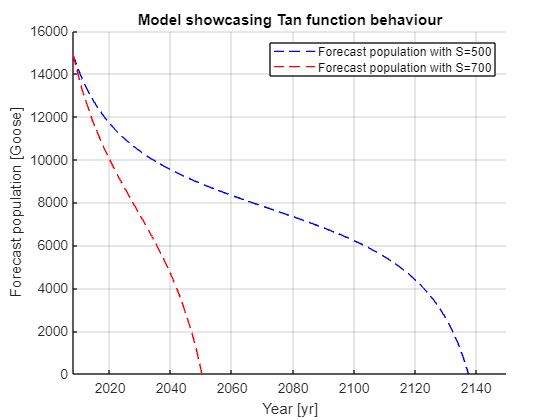


%re-plotting 
fplot(P,"--r")

hold off %end of plotting

%setting limits
xlim([2008 2150])
ylim([0 16000])

%labelling graph
xlabel("Year [yr]")
ylabel("Forecast population [Goose]")
title("Model showcasing Tan function behaviour")
legend("Forecast population with S=500", ...
    "Forecast population with S=700", ...
    "Location",...
    "northeast"...
    )

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;
grid on;

function R = rsq(a,b,x_array,y_array)
%function calculating rsquared for a f(a,b,x) where a & b are coefficients

syms x %declaring symbolic variables

f(x) = a*exp(b*x);
%formula usd https://www.ncl.ac.uk/webtemplate/ask-assets/external/maths-resources/statistics/regression-and-correlation/coefficient-of-determination-r-squared.html


    avg = mean(y_array);%calculating average of y values
    ssr = 0; %initiating sum squares regression
    sst = 0; %initiating total sum of squares
    
    %looping through all values
    for i=1:length(x_array)

        ssr = ssr + ((y_array(i) - f(x_array(i)))^2); %summing over ssr

        sst = sst + ((y_array(i) - avg)^2); %summing over sst

    end

    R = eval(1-(ssr/sst)); %calculating R^2
end

function R = rsq1(Pe,Po,r,x_array,y_array)
%function calculating rsquared for a f(Pe,Po,r,x) where a & b are coefficients

syms x %declaring symbolic variables

f(x) = Pe/(1+((Pe/Po)*exp(-r*x)));
%formula usd https://www.ncl.ac.uk/webtemplate/ask-assets/external/maths-resources/statistics/regression-and-correlation/coefficient-of-determination-r-squared.html


    avg = mean(y_array);%calculating average of y values
    ssr = 0; %initiating sum squares regression
    sst = 0; %initiating total sum of squares
    
    %looping through all values
    for i=1:length(x_array)

        ssr = ssr + ((y_array(i) - f(x_array(i)))^2); %summing over ssr

        sst = sst + ((y_array(i) - avg)^2); %summing over sst

    end

    R = eval(1-(ssr/sst)); %calculating R^2
end